## 3. An example - a lipid monolayer.

In the next chapter, we'll look in detail how to set up the problem definition for a given situation. Initially though, it's useful to take a pre-prepared problem definition, and to see how this is then used in RAT. As an example, we'll use some neutron reflectivity data for a lipid monolayer, collected at various deuterations, which we want to analyse simultaneously.

In terms of reflectivity, the interface we want to model (i.e. a monolayer at an air-water interface) is usually well modeled by two layers: the hydrophobic tail regions of the lipids, which locate outside the bulk water interface, and the hydrophilic heads wich are adjacent (or embedded) in the bulk aqueous phase. 

In our example, the layers can be either deuterated of hydrogenated, and the bulk water can either be D2O or ACMW.

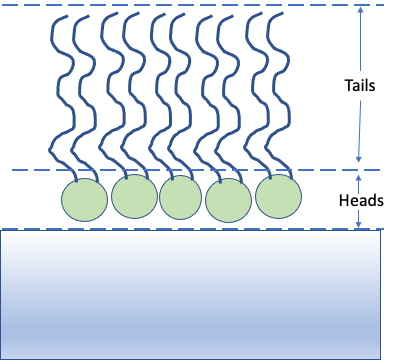

The way this kind of model is set up for RAT should be familliar to anyone who has used RasCAL, in that we identify which parameters we need to describe the model, group these into layers, and then group the layers along with data into contrasts. The advantage pf this approach is that it's simple to share parameters beytween layers, so a layer representing deuterated headgroups should share the same thickness and roughness parameters as a layer representing hydrogenated heads, but they should differ from each other in their SLD. 

The problem definition in RAT is done by making an instance of a project class, and then using the class methods to then set the layers and so on. But for now, we'll look at a pre-prepared example.

root = getappdata(0,'root');
addpath(fullfile(root,'examples','manual', 'DSPCStandardLayers'));

% Load in a pre-made problemDef class
problem = load('twoContrastExample.mat');
problem = problem.problem;

% Make an instance of a projectClass:
problem = projectClass('test');

% Check what type our class is...
class(problem)

% Have a look at its class methods..
methods(problem)

% Check our empty project class:
disp(problem)

% Make an instance of the controlsClass
controls = controlsClass();

disp(controls)

rmpath(fullfile(root,'examples','manual', 'DSPCStandardLayers'));